[x,Fs] = audioread('StarWars4.wav'); NBITS=16;
[y,Fs] = audioread('StarWars4_out.wav'); NBITS=16;
Fs

Fs = 44100

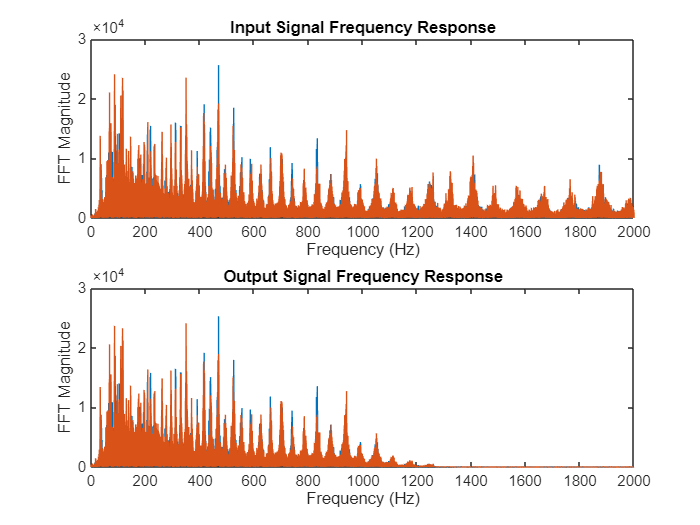

X = fft(x);
Y = fft(y);
w = linspace(0,2,length(X));

figure();
subplot(2,1,1);
plot(Fs*w/2,abs(X));
xlim([0,2000]);
xlabel('Frequency (Hz)');
ylabel('FFT Magnitude');
title('Input Signal Frequency Response');

subplot(2,1,2);
plot(Fs*w/2,abs(Y));
xlim([0,2000]);
xlabel('Frequency (Hz)');
ylabel('FFT Magnitude');
title('Output Signal Frequency Response');